close all; clear all; clc;
warning("off")

# ODA Exam fall 2017

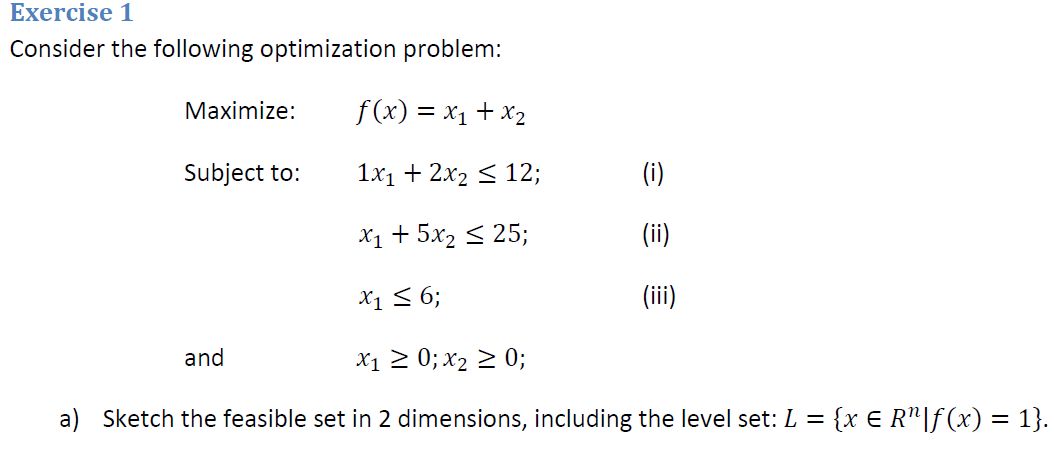

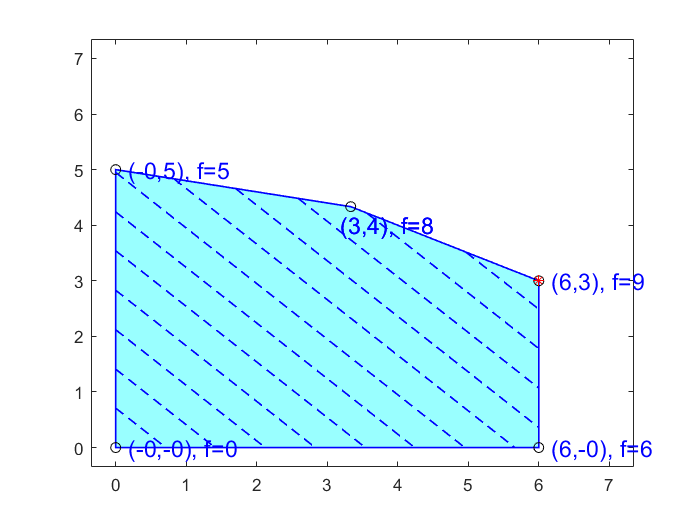

Optimal solution found.



Optimal solution found.


Optimal solution found.



A = [[1 2];   % x1 + 2x2 <= 12
     [1 5];   %  x1 +  5x2 <= 25
     [1 0];   %  x1+  0x2 <= 6
     [-1 0];  % non-negativity constraint x>=0
     [0 -1];  % non-negativity constraint y>=0
    ];
b = [12;
     25;
     6;
     0;
     0;
    ];
lower_b = [0; 0];
upper_b = [7; 7];
c = [1; 1];
figure(1);
    plot_feasible(A, b, c, lower_b, upper_b, ...
		  'linecolor', 'b', ...
		  'linestyle', '-', ...
		  'filllinestyle', '--', ...
		  'backgroundcolor', [0.6 1 1], ...
		  'linesep', 0.5, ...
		  'plot_vertices', 'ko', ...
		  'label_vertices', 3, ...
		  'label_vertices_size', 14, ...
		  'label_vertices_prec', 0, ...
		  'label_vertices_color', 'b', ...
		  'plot_max', 'r*');

**Spørgsmål til denne ?? Hvor kommer 3,4 fra ???**

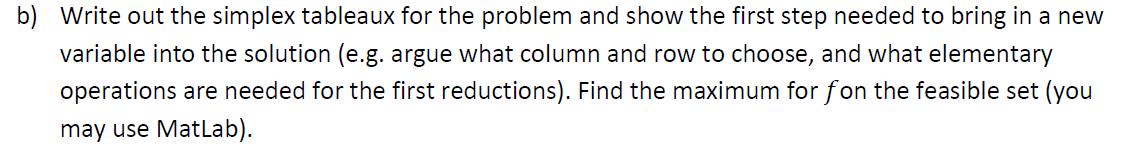

% Simplex tuable for the problem  
% Step change inquality to equality by adding slacks var
%    x1   x2, s1  s2  s3  M   B  
A = [1,   2,  1,  0,  0,  0,  12;
     1,   5,  0,  1,  0,  0,  25;
     1,   0,  0,  0,  1,  0,  6;
     -1, -1,  0,  0,  0,  1,  0]

A =      1     2     1     0     0     0    12
     1     5     0     1     0     0    25
     1     0     0     0     1     0     6
    -1    -1     0     0     0     1     0


% Step two, find most negative --> they are equal -- we take x1
% Step three a positive ratio than is smallets 
% B/entry  for all entries
% 12/1 = 12  |   25/1 = 25    |    6/1 = 6     --> pivot x1 at row2

% Row operations to finish pivot collum

% R4 + R3
A(4,:) =  A(3,:) + A(4,:);

% R2 - R3
A(2,:) = A(2,:)-A(3,:);

% R1 - R3
A(1,:) = A(1,:)-A(3,:);

A

A =      0     2     1     0    -1     0     6
     0     5     0     1    -1     0    19
     1     0     0     0     1     0     6
     0    -1     0     0     1     1     6


% repeat step 2
% Most negative = x2
% best ratio
% 6/2 = 3     |      19/5 = 3,8      --> row 1

% Row operations to finish pivot collum

% R1 /2
A(1,:) = A(1,:) * 1/2;

% R2 - 5*R1 
A(2,:) = A(2,:) - 5*A(1,:);

% R4 + R1
A(4,:) = A(1,:) + A(4,:); 

A

A =          0    1.0000    0.5000         0   -0.5000         0    3.0000
         0         0   -2.5000    1.0000    1.5000         0    4.0000
    1.0000         0         0         0    1.0000         0    6.0000
         0         0    0.5000         0    0.5000    1.0000    9.0000


x1 = optimvar('x1');
x2 = optimvar('x2');
prob = optimproblem('Objective',x1 +x2,'ObjectiveSense','max');
prob.Constraints.c1 = 1*x1 + 2*x2 <= 12;
prob.Constraints.c2 = x1 +5*x2 <= 25;
prob.Constraints.c3 = x1 <= 6;
prob.Constraints.c4 = x1 >= 0;
prob.Constraints.c5 = x2 >= 0;

problem = prob2struct(prob);

[sol,fval,exitflag,output] = linprog(problem);

Optimal solution found.



sol

sol =     6.0000
    3.0000


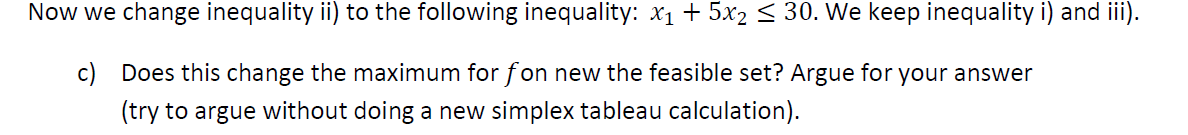

% No it does not increase the maximum for f on the new feasible set.  The
% reason is that we dont have a final pivot row where the inequallty is
% included. Even tho we increase it, the final maximum solution whould
% still be the same.

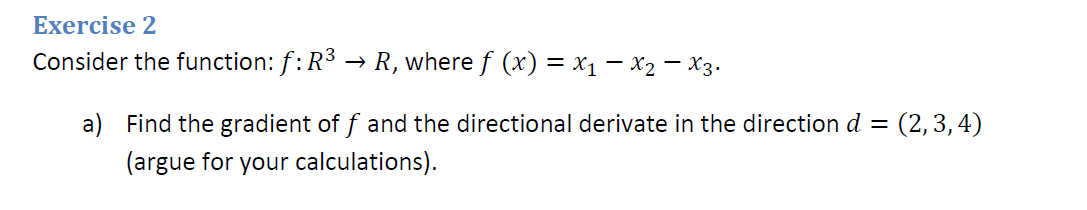

Gradiant of f is defined as : $\nabla f\left(x\right)=\left\lbrack \begin{array}{c}
\frac{\partial f}{\partial {\;x}_1 }\\
\frac{\partial f}{\partial {\;x}_2 }\\
\ldotp \ldotp \ldotp \\
\frac{\partial f}{\partial {\;x}_n }
\end{array}\right\rbrack \;$   First derivative-row vector is defined as : $D\;f\left(x\right)={\left(\nabla f\left(x\right)\right)}^T =\left\lbrack \begin{array}{cccc}
\frac{\partial f}{\partial {\;x}_1 } & \frac{\partial f}{\partial {\;x}_2 } & \ldotp \ldotp \ldotp  & \frac{\partial f}{\partial {\;x}_n }
\end{array}\right\rbrack$

We parcial differiance first for x1, then x2 and lastly 3 to get the gradiant $\nabla f\left(x\right)$

syms x1 x2 x3;
f = x1-x2-x3;
gradiant = gradient(f, [x1,x2, x3])

$$gradiant = \left(\begin{array}{c} 1\\ -1\\ -1 \end{array}\right)$$

We can then obtian the directional dirivitive : ${\left(\nabla f\left(x\right)\right)}^T *d$

d = [2,3,4]';
directional_derivative = gradiant'*d

$$directional\_derivative = -5$$

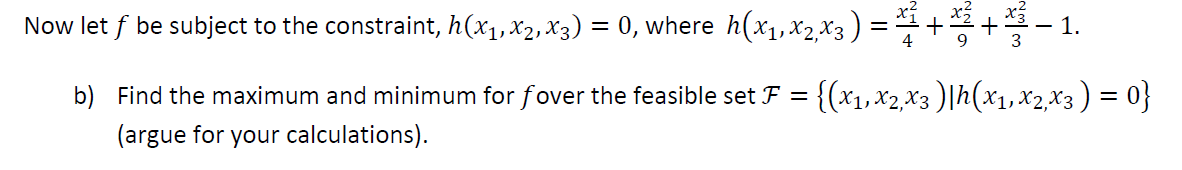

First we find critical points

HELPPPPPPPP

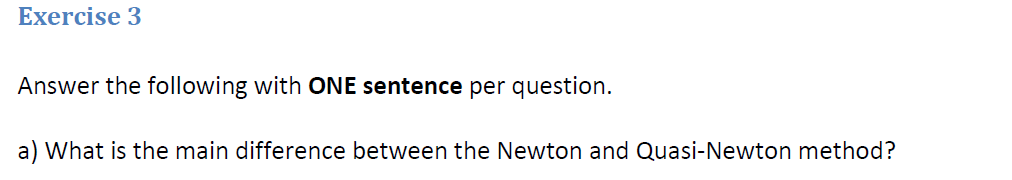

Newton method needs both gradiant and hessain computed which can be comutational expensive. For larger problems Quasi-Newton is has a much faster converging time since it doenst need recalculation of the gradiant and hessian.

Discrete optimazation involves a optimazation prolem where you have a dat set of discrete values. An example  discrete optimazation could invovle a subset og natural integers, the dataset must be finite. GPS "The shortes path"